%clear;
mu_0=4*pi*10^(-7);
R=0.1;

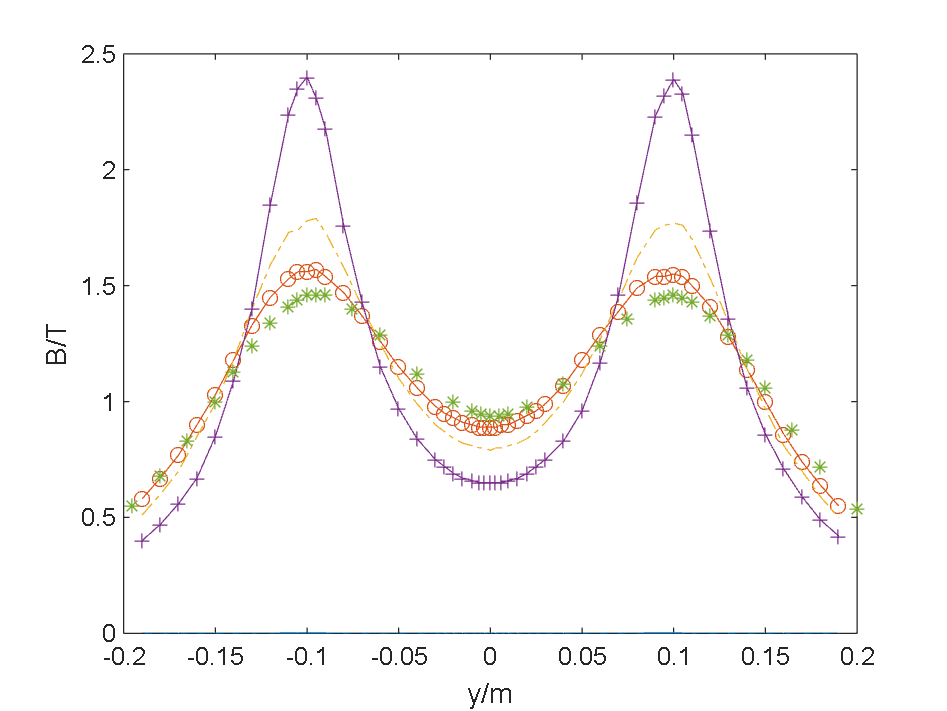

%实测部分
my_data=xlsread('data.xlsx');
I_S0=5;%5mA
K_H=171;%mV/mA
for i=2
    my_data(1:end,i)=my_data(1:end,i)./(K_H*I_S0);
end    
data1=my_data(1:end,1:2)';%0.5A 2R left 2cm 霍尔工作电流 5.00mA
data2=my_data(1:end,3:4)';%0.5A 2R left 4cm 霍尔工作电流 5.00mA
data3=my_data(1:end,5:6)';%0.5A 2R left 6cm 霍尔工作电流 5.00mA
data4=my_data(1:end,7:8)';%0.5A 2R left 8cm 霍尔工作电流 5.00mA
data5=my_data(1:41,9:10)';%0.5A R left 2cm 霍尔工作电流 5.00mA
data6=my_data(1:41,11:12)';%0.5A R left 2cm 霍尔工作电流 5.00mA
data7=my_data(1:41,13:14)';%0.5A R left 2cm 霍尔工作电流 5.00mA
data8=my_data(1:41,15:16)';%0.5A R left 2cm 霍尔工作电流 5.00mA
data9=my_data(1:47,17:18)';%0.5A 0.5R left 2cm 霍尔工作电流 5.00mA
data10=my_data(1:47,19:20)';%0.5A 0.5R left 2cm 霍尔工作电流 5.00mA
data11=my_data(1:47,21:22)';%0.5A 0.5R left 2cm 霍尔工作电流 5.00mA
data12=my_data(1:47,23:24)';%0.5A 0.5R left 2cm 霍尔工作电流 5.00mA
data13=my_data(1:37,25:26)';%0.5A 2R center 霍尔工作电流 5.00mA
data14=my_data(1:29,27:28)';%0.5A R center 霍尔工作电流 5.00mA
data15=my_data(1:30,29:30)';%0.5A 0.5R center 霍尔工作电流 5.00mA

x1=data1(1,1:end)/100;
x2=data5(1,1:end)/100;
x3=data9(1,1:end)/100;
y=(-8:2:7)/100;

plot(x1,data1(2,1:end),'-',x1,data2(2,1:end),'-o',x1,data3(2,1:end),'-.',x1,data4(2,1:end),'-+');%2R
hold on
plot(data13(1,1:end)/100,data13(2,1:end),'*');
xlabel('y/m');
ylabel('B/T');
hold off

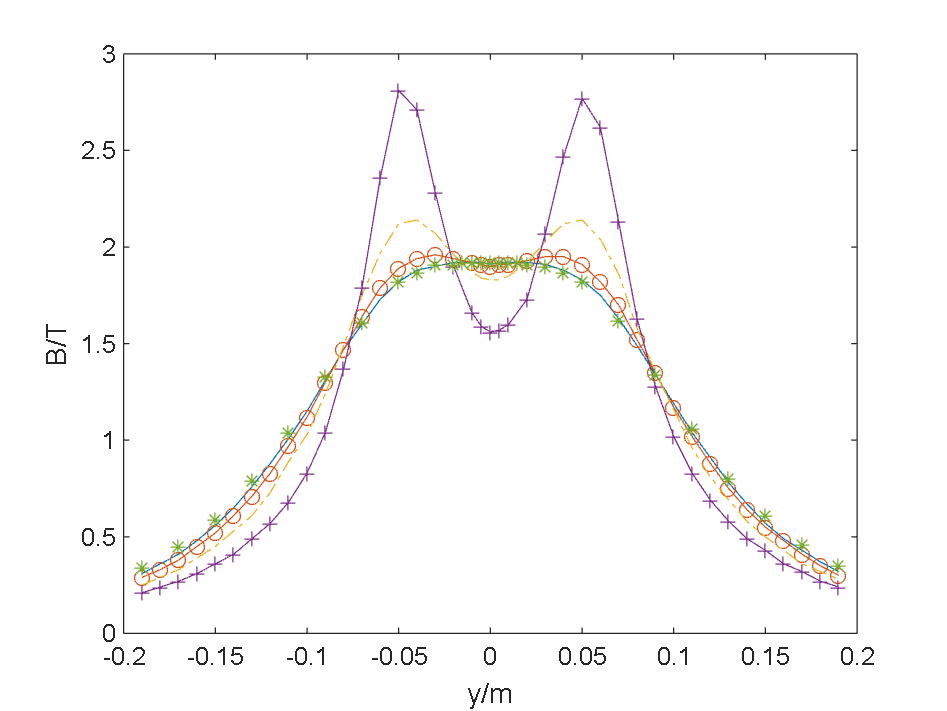

plot(x2,data5(2,1:end),'-',x2,data6(2,1:end),'-o',x2,data7(2,1:end),'-.',x2,data8(2,1:end),'-+');%R
hold on
plot(data14(1,1:end)/100,data14(2,1:end),'*');
hold off
xlabel('y/m');
ylabel('B/T');

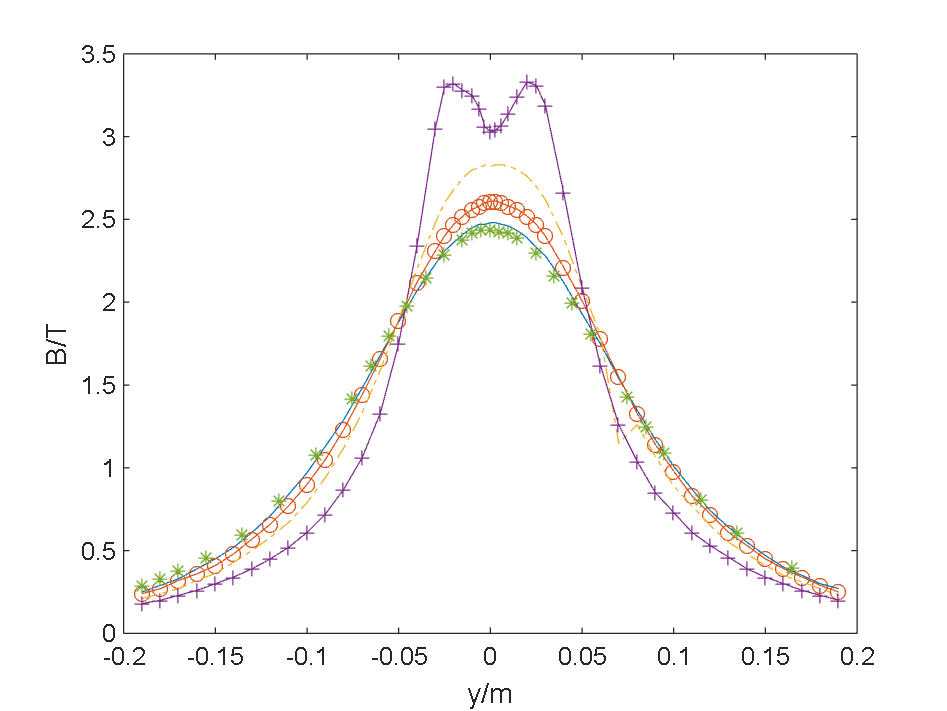

plot(x3,data9(2,1:end),'-',x3,data10(2,1:end),'-o',x3,data11(2,1:end),'-.',x3,data12(2,1:end),'-+');%0.5R
hold on
plot(data15(1,1:end)/100,data15(2,1:end),'*');
hold off
xlabel('y/m');
ylabel('B/T');

[X1,Y1]=meshgrid(x1,y);
data_a=[data1(2,1:end);data2(2,1:end);data3(2,1:end);data4(2,1:end)]

data_a =     0.0007    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0016    0.0015    0.0013    0.0012    0.0010    0.0009    0.0008
    0.5800    0.6700    0.7700    0.9000    1.0300    1.1800    1.3300    1.4500    1.5300    1.5600    1.5600    1.5700    1.5400    1.4700    1.3700    1.2600    1.1500    1.0600    0.9800    0.9500    0.9300    0.9100    0.9000    0.8900    0.8900    0.8900    0.8900    0.9000    0.9000    0.9200    0.9400    0.9600    0.9900    1.0700    1.1800    1.2900    1.3900    1.4900    1.5400    1.5400    1.5500    1.5400    1.5000    1.4100    1.2800    1.1400    1.0000    0.8600    0.7400

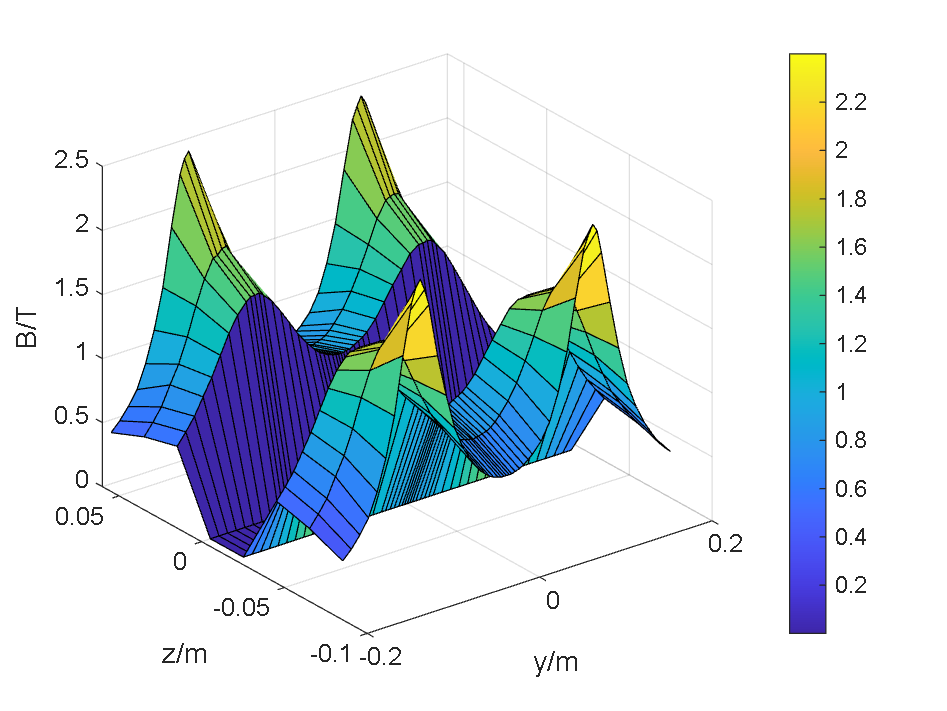

data_a=[flipud(data_a);data_a];
surf(X1,Y1,data_a);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
colorbar

[X2,Y2]=meshgrid(x2,y);
data_b=[data5(2,1:end);data6(2,1:end);data7(2,1:end);data8(2,1:end)]

data_b =     0.3100    0.3600    0.4100    0.4800    0.5600    0.6500    0.7600    0.8800    1.0100    1.1500    1.3100    1.4700    1.6000    1.7300    1.8200    1.8800    1.9000    1.9200    1.9200    1.9200    1.9100    1.9200    1.9200    1.9200    1.9100    1.8800    1.8300    1.7500    1.6300    1.4900    1.3400    1.1900    1.0400    0.9100    0.7800    0.6700    0.5700    0.4900    0.4300    0.3700    0.3200
    0.2900    0.3300    0.3800    0.4500    0.5200    0.6100    0.7100    0.8300    0.9700    1.1200    1.3000    1.4700    1.6400    1.7900    1.8900    1.9400    1.9600    1.9400    1.9200    1.9100    1.9000    1.9100    1.9100    1.9300    1.9500    1.9500    1.9100    1.8200    1.7000    1.5200    1.3500    1.1700    1.0200    0.8800    0.7500    0.6400    0.5500    0.4800    0.4100    0.3500    0.3000
    0.2500    0.2900    0.3300    0.3900    0.4500    0.5300    0.6100    0.7300    0.8900    1.0300    1.2400    1.4900    1.7500    1.9700    2.1200    2.1400    2.070

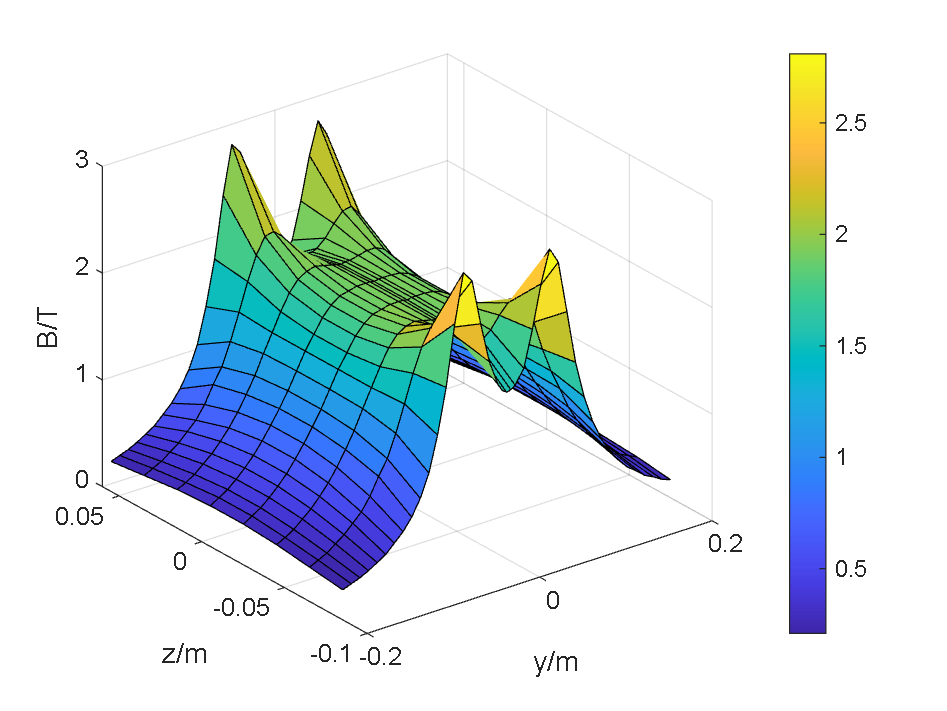

data_b=[flipud(data_b);data_b];
surf(X2,Y2,data_b);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
colorbar

[X3,Y3]=meshgrid(x3,y);
data_c=[data9(2,1:end);data10(2,1:end);data11(2,1:end);data12(2,1:end)]

data_c =     0.2500    0.2900    0.3300    0.3900    0.4500    0.5200    0.6100    0.7100    0.8400    0.9700    1.1300    1.2900    1.4800    1.6800    1.8800    2.0700    2.2300    2.3100    2.3600    2.4100    2.4500    2.4700    2.4700    2.4800    2.4800    2.4700    2.4600    2.4300    2.3900    2.3300    2.2800    2.1200    1.9300    1.7500    1.5400    1.3500    1.1700    1.0100    0.8700    0.7400    0.6400    0.5500    0.4700    0.4000    0.3500    0.3000    0.2700
    0.2400    0.2700    0.3200    0.3600    0.4100    0.4800    0.5700    0.6600    0.7700    0.9000    1.0500    1.2300    1.4400    1.6600    1.8900    2.1200    2.3100    2.4000    2.4700    2.5200    2.5600    2.5800    2.6000    2.6100    2.6100    2.6000    2.5800    2.5600    2.5200    2.4700    2.4000    2.2100    2.0100    1.7800    1.5500    1.3300    1.1400    0.9800    0.8300    0.7200    0.6100    0.5300    0.4500    0.3900    0.3400    0.2900    0.2500
    0.2100    0.2400    0.2700    0.3200    0.363

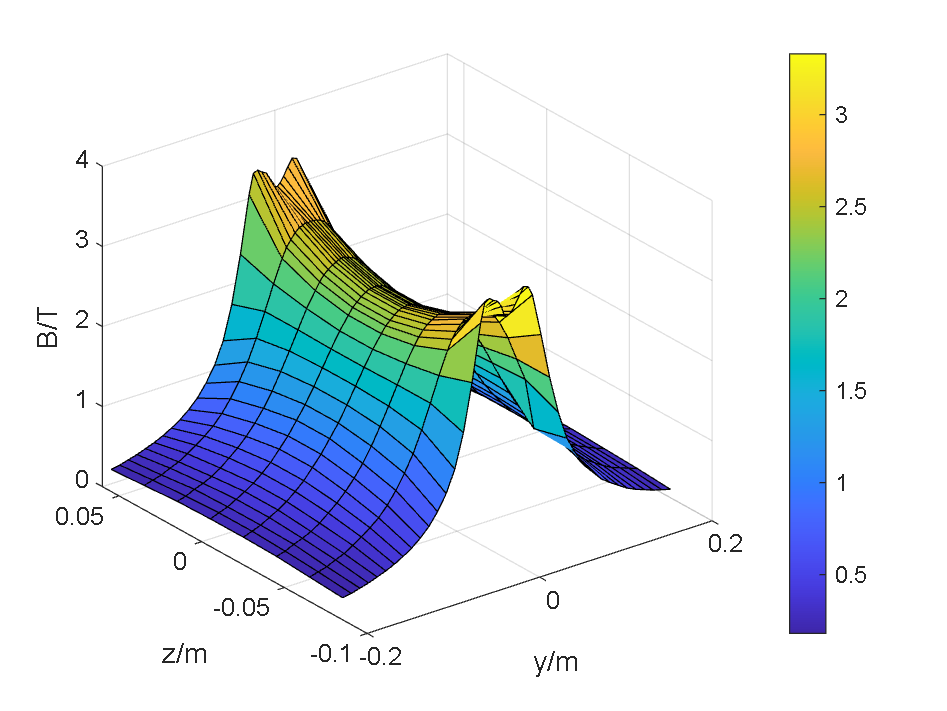

data_c=[flipud(data_c);data_c];
surf(X3,Y3,data_c);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
colorbar

y_a=data1(1,1:end)/100;
z_a=(-8:2:8)/100;
z_a(5)=[];
[YA,ZA]=meshgrid(y_a,z_a);
value_add=0;
weight_sum=0;
L=2*R;
for i=1:size(YA,1)
    for j=1:size(YA,2)
        f1=@(x)abs(cal_coil(YA(i,j),ZA(i,j),x,L)-data_a(i,j));
        %x0=fmincon(f,[0.0005,15,20],[],[],[],[],[0,1,1],[0.0012,30,40]);
        x1=ga(f1,3,[],[],[],[],[0.0005 ,10,10],[0.0012,30,30],[],[]);
        % f1(x1)+data_a(i,j)
        % data_a(i,j)
        value_add=value_add+f1(x1);
        weight_sum=weight_sum+x1*f1(x1);
    end
end

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


x_mean1=weight_sum/value_add

y_b=data5(1,1:end)/100;
z_b=(-8:2:8)/100;
z_b(5)=[];
[YB,ZB]=meshgrid(y_b,z_b);
value_add=0;
weight_sum=0;
L=R;
for i=1:size(YB,1)
    for j=1:size(YB,2)
        f2=@(x)abs(cal_coil(YB(i,j),ZB(i,j),x,L)-data_b(i,j));
        x2=ga(f2,3,[],[],[],[],[0.0005 ,10,10],[0.0012,30,30],[],[]);
        value_add=value_add+f2(x2);
        weight_sum=weight_sum+x2*f2(x2);
    end
end
x_mean2=weight_sum/value_add

y_c=data9(1,1:end)/100;
z_c=(-8:2:8)/100;
z_c(5)=[];
[YC,ZC]=meshgrid(y_c,z_c);
value_add=0;
weight_sum=0;
L=R/2;
for i=1:size(YC,1)
    for j=1:size(YC,2)
        f3=@(x)abs(cal_coil(YC(i,j),ZC(i,j),x,L)-data_c(i,j));
        x3=ga(f3,3,[],[],[],[],[0.0005 ,10,10],[0.0012,30,30],[],[]);
        value_add=value_add+f3(x3);
        weight_sum=weight_sum+x3*f3(x3);
    end
end
x_mean3=weight_sum/value_add
x_mean=(x_mean1+x_mean2+x_mean3)/3

%理论计算部分
x=0;
y=-0.2:0.01:0.2;
z=-0.08:0.02:0.08;
z(5)=[];
I=0.5;%励磁电流0.5A
[Y,Z]=meshgrid(y,z);
X=x*ones(9,41);
L=2*R;
clear B;
for i=1:size(Y,1)
    for j=1:size(Y,2)
        B(i,j)=cal_coil(Y(i,j),Z(i,j),x_mean,L);
    end
end
surf(Y,Z,B);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
L=R;
for i=1:size(Y,1)
    for j=1:size(Y,2)
        B(i,j)=cal_coil(Y(i,j),Z(i,j),x_mean,L);
    end
end
surf(Y,Z,B);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');

L=0.5*R;
for i=1:size(Y,1)
    for j=1:size(Y,2)
        B(i,j)=cal_coil(Y(i,j),Z(i,j),x_mean,L);
    end
end
surf(Y,Z,B);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');

distance1=0;
distance2=0;
distance3=0;
for i=1:size(YA,1)
    for j=1:size(YA,2)
        distance1=distance1+abs(cal_coil(YA(i,j),ZA(i,j),x_mean,2*R)-data_a(i,j));        
    end
end
for i=1:size(YB,1)
    for j=1:size(YB,2)
        distance2=distance2+abs(cal_coil(YB(i,j),ZB(i,j),x_mean,R)-data_b(i,j));        
    end
end
for i=1:size(YC,1)
    for j=1:size(YC,2)
        distance3=distance3+abs(cal_coil(YC(i,j),ZC(i,j),x_mean,R/2)-data_c(i,j));        
    end
end

for i=1:size(YA,1)
    for j=1:size(YA,2)
        B_check1(i,j)=cal_coil(YA(i,j),ZA(i,j),x_mean,2*R);
    end
end
surf(YA,ZA,B_check1);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
colorbar
for i=1:size(YB,1)
    for j=1:size(YB,2)
        B_check2(i,j)=cal_coil(YB(i,j),ZB(i,j),x_mean,R);
    end
end
surf(YB,ZB,B_check2);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
colorbar
for i=1:size(YC,1)
    for j=1:size(YC,2)
        B_check3(i,j)=cal_coil(YC(i,j),ZC(i,j),x_mean,R/2);
    end
end
surf(YC,ZC,B_check3);
xlabel('y/m');
ylabel('z/m');
zlabel('B/T');
colorbar
distance1=distance1/size(YA,2)/size(YA,1)
distance2=distance2/size(YB,2)/size(YB,1)
distance3=distance3/size(YC,2)/size(YC,1)
avg_distance=(distance1+distance2+distance3)/3


clear cst_data;
cst_data=textread('coil_2R.txt');
cst_y=-cst_data(1:end,3)/100;
cst_z=-cst_data(1:end,2)/100;
cst_By=-cst_data(1:end,6);
cst_Bz=-cst_data(1:end,5);
distance_csty=0;
distance_cstz=0;
for i=1:size(cst_y,1)
    distance_csty=distance_csty+abs(cal_coil(cst_y(i),cst_z(i),x_mean,2*R)-cst_By(i))/abs(cst_By(i));
    distance_cstz=distance_cstz+abs(cal_coil_z(cst_y(i),cst_z(i),x_mean,2*R)-cst_Bz(i))/abs(cst_Bz(i));    
end
mean(cst_By)
mean(cst_Bz)
distance_csty/size(cst_y,1)
distance_cstz/size(cst_z,1)

function val=cal_coil(posy,posz,x,L)
R=0.1;
mu_0=4*pi*10^(-7);
I=0.5;%励磁电流0.5A
x1=x(1);%线径
x2=floor(x(2));%厚度层数z方向
x3=floor(x(3));%宽度层数y方向
B1=0;B2=0;
for m=0:(x2-1)
    for n=0:(x3-1)
        L_alter=(0.5*L+(n-0.5*x3+0.5)*x1)*2;
        R_alter=R+(m-0.5*x2+0.5)*x1;
        k1=sqrt(4*(R+(m-0.5*x2+0.5)*x1)*abs(posz)/((abs(posz)+R+(m-0.5*x2+0.5)*x1)^2+(posy-(0.5*L_alter))^2));
        k2=sqrt(4*(R+(m-0.5*x2+0.5)*x1)*abs(posz)/((abs(posz)+R+(m-0.5*x2+0.5)*x1)^2+(posy+0.5*L_alter)^2));
        [K1,E1]=ellipke(k1);
        [K2,E2]=ellipke(k2);
        B1=B1+(mu_0*I/(2*pi))   /   sqrt((abs(posz)+R+(m-0.5*x2+0.5)*x1)^2+(posy-(0.5*L_alter))^2)   *(E1*(R^2-(posz)^2-(posy-(0.5*L_alter))^2)/((abs(posz)-(R+(m-0.5*x2+0.5)*x1))^2+(posy-(0.5*L_alter))^2)+K1);
        B2=B2+(mu_0*I/(2*pi))   /   sqrt((abs(posz)+R+(m-0.5*x2+0.5)*x1)^2+(posy+(0.5*L_alter))^2)   *(E2*(R^2-(posz)^2-(posy+(0.5*L_alter))^2)/((abs(posz)-(R+(m-0.5*x2+0.5)*x1))^2+(posy+(0.5*L_alter))^2)+K2);

    end
end
val=B1+B2;
end

function val=cal_coil_z(posy,posz,x,L)
R=0.1;
mu_0=4*pi*10^(-7);
I=0.5;%励磁电流0.5A
const=mu_0*I/2/pi;
x1=x(1);%线径
x2=floor(x(2));%厚度层数z方向
x3=floor(x(3));%宽度层数y方向

B1=0;B2=0;
for m=0:(x2-1)
    for n=0:(x3-1)
        L_alter=(0.5*L+(n-0.5*x3+0.5)*x1)*2;
        R_alter=R+(m-0.5*x2+0.5)*x1;
        k1=sqrt(4*(R_alter)*abs(posz)/((abs(posz)+R_alter)^2+(posy-(0.5*L_alter))^2));
        k2=sqrt(4*(R_alter)*abs(posz)/((abs(posz)+R_alter)^2+(posy+0.5*L_alter)^2));
        [K1,E1]=ellipke(k1);
        [K2,E2]=ellipke(k2);
        B1=const*(posy-0.5*L_alter)/(posz*sqrt((abs(posz)+R_alter)^2+(posy-0.5*L_alter)^2))*((R_alter^2+posz^2+(posy-0.5*L_alter)^2)/((abs(posz)-R_alter)^2+(posy-0.5*L_alter)^2)*E1-K1);
        B2=const*(posy+0.5*L_alter)/(posz*sqrt((abs(posz)+R_alter)^2+(posy+0.5*L_alter)^2))*((R_alter^2+posz^2+(posy+0.5*L_alter)^2)/((abs(posz)-R_alter)^2+(posy+0.5*L_alter)^2)*E2-K2);
    end
end
val=B1+B2;
end